n = 20;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsystem(H,b);

LUSystem



x_g = Gsystem(H,b);

GSystem




norm(x_lu - e)

ans =      1.098809081399329e+02


norm(x_g - e)

ans =      9.519992905038327e+05



alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    b_n = b + alpha*e;
    x = Gsystem(A,b);
    d(i) = norm(x - e);
end

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

GSystem

G

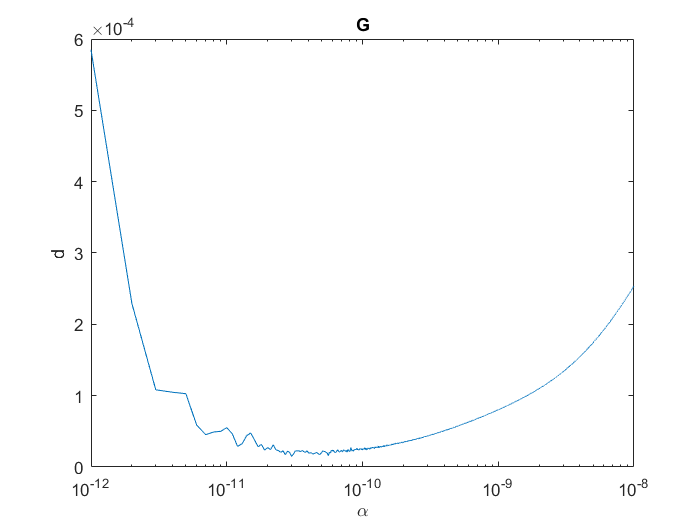

semilogx(alpha*(1:1e4),d);
title('G');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      3.000000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.493031621638385e-05



alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    b_n = b + alpha*e;
    x = LUsystem(A,b);
    d(i) = norm(x - e);
end

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem

LUSystem



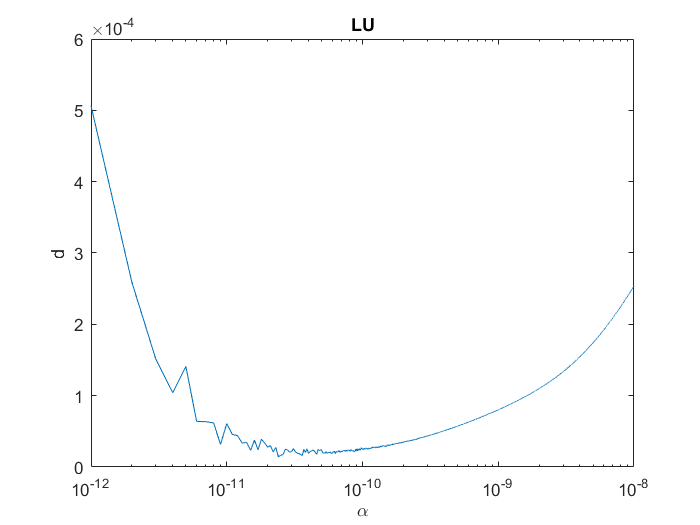

semilogx(alpha*(1:1e4),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      2.400000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.426026695365296e-05
